%% ============================================================
% SINGLE-PHOTON SCANNING CAMERA
%
% V3 - POISSON MAXIMUM-LIKELIHOOD RECONSTRUCTION
%
% Reconstruction method:
% Richardson-Lucy iterative reconstruction
%
% Measurement model:
%
% True star image
%       ↓
% Optical PSF + fibre response
%       ↓
% Photon detection
%       ↓
% Dark counts
%       ↓
% Poisson photon statistics
%       ↓
% Measured SPCM counts
%       ↓
% Dark-count correction
%       ↓
% Richardson-Lucy reconstruction
%       ↓
% Estimated star image
%
% ============================================================

clear;
clc;
close all;


%% ============================================================
% 1. TELESCOPE AND FIBRE
% ============================================================

FOCAL_LENGTH = 6459e-3;       % m

FIBRE_DIAMETER = 4.2e-6;      % m

FIBRE_DIAMETER_UM = 4.2;      % um


angularSamplingRad = ...
    FIBRE_DIAMETER / FOCAL_LENGTH;

angularSamplingArcsec = ...
    angularSamplingRad * (180/pi) * 3600;


fprintf('Angular sampling = %.4f arcsec\n', ...
    angularSamplingArcsec);

Angular sampling = 0.1341 arcsec


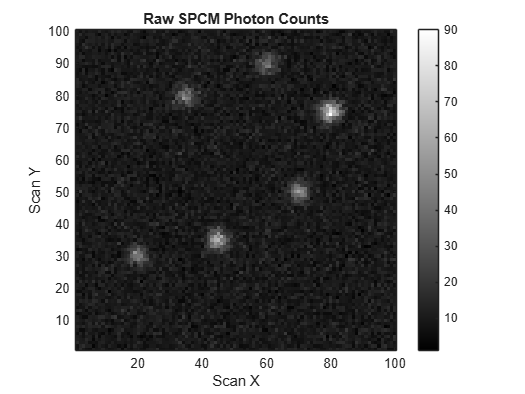



%% ============================================================
% 2. IMAGE GRID
% ============================================================

IMAGE_WIDTH  = 100;
IMAGE_HEIGHT = 100;

PIXEL_SIZE_UM = FIBRE_DIAMETER_UM;


x = ((1:IMAGE_WIDTH) - (IMAGE_WIDTH+1)/2) ...
    * PIXEL_SIZE_UM;

y = ((1:IMAGE_HEIGHT) - (IMAGE_HEIGHT+1)/2) ...
    * PIXEL_SIZE_UM;

[X,Y] = meshgrid(x,y);


%% ============================================================
% 3. CREATE TRUE STAR IMAGE
% ============================================================

trueImage = zeros(IMAGE_HEIGHT,IMAGE_WIDTH);


% [X, Y, brightness]

stars = [
    20, 30, 10e6;
    45, 35, 15e6;
    70, 50, 12e6;
    80, 75, 20e6;
    35, 80, 10e6;
    60, 90, 8e6
];


%% ============================================================
% 4. STAR PSF
% ============================================================

PSF_SIGMA_PIXELS = 1.5;

PSF_SIGMA_UM = ...
    PSF_SIGMA_PIXELS * PIXEL_SIZE_UM;


for k = 1:size(stars,1)

    starX = ...
        (stars(k,1) - (IMAGE_WIDTH+1)/2) ...
        * PIXEL_SIZE_UM;

    starY = ...
        (stars(k,2) - (IMAGE_HEIGHT+1)/2) ...
        * PIXEL_SIZE_UM;

    brightness = stars(k,3);


    gaussianStar = brightness * ...
        exp( ...
        -((X-starX).^2 + (Y-starY).^2) ...
        /(2*PSF_SIGMA_UM^2) );


    trueImage = trueImage + gaussianStar;

end


%% ============================================================
% 5. CREATE SYSTEM PSF
% ============================================================

% The reconstruction algorithm needs an estimate of the
% spatial response of the imaging system.
%
% For this example we model it as a Gaussian PSF.

PSF_SIZE = 11;

psfAxis = ...
    -floor(PSF_SIZE/2):floor(PSF_SIZE/2);

[PSFX,PSFY] = meshgrid(psfAxis,psfAxis);


systemPSF = ...
    exp(-(PSFX.^2 + PSFY.^2) ...
    /(2*PSF_SIGMA_PIXELS^2));


% Normalise PSF

systemPSF = ...
    systemPSF / sum(systemPSF(:));


%% ============================================================
% 6. CREATE FIBRE-SAMPLED OPTICAL IMAGE
% ============================================================

% Convolve true image with system response.

blurredImage = ...
    conv2(trueImage,systemPSF,'same');


%% ============================================================
% 7. DETECTOR PARAMETERS
% ============================================================

PDE = 0.65;

DARK_COUNT_RATE = 101;       % Hz

INTEGRATION_TIME = 0.1;      % seconds


% Photon scaling controls how difficult the reconstruction is.

PHOTON_SCALE = 1e-4;


%% ============================================================
% 8. CREATE PHOTON-LIMITED MEASUREMENTS
% ============================================================

expectedSignal = ...
    blurredImage * ...
    PHOTON_SCALE * ...
    PDE * ...
    INTEGRATION_TIME;


expectedDark = ...
    DARK_COUNT_RATE * ...
    INTEGRATION_TIME;


expectedCounts = ...
    expectedSignal + expectedDark;


% Photon counting follows Poisson statistics.

measuredCounts = ...
    poissrnd(expectedCounts);


%% ============================================================
% 9. DISPLAY RAW MEASUREMENTS
% ============================================================

figure;

imagesc(measuredCounts);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('Raw SPCM Photon Counts');

xlabel('Scan X');
ylabel('Scan Y');



%% ============================================================
% 10. REMOVE EXPECTED DARK COUNTS
% ============================================================

signalCounts = ...
    measuredCounts - expectedDark;


% Prevent negative values

signalCounts(signalCounts < 0) = 0;


%% ============================================================
% 11. INITIAL RECONSTRUCTION ESTIMATE
% ============================================================

% Start with a uniform positive image.

estimate = ...
    ones(size(signalCounts));


%% ============================================================
% 12. RICHARDSON-LUCY ITERATIVE RECONSTRUCTION
% ============================================================

NUM_ITERATIONS = 30;


% Flip PSF for the correction step

psfFlipped = rot90(systemPSF,2);


fprintf('\n');
fprintf('Starting Richardson-Lucy reconstruction...\n');

Starting Richardson-Lucy reconstruction...




for iteration = 1:NUM_ITERATIONS


    %% --------------------------------------------------------
    % Predict what detector would measure
    % ---------------------------------------------------------

    predictedCounts = ...
        conv2(estimate,systemPSF,'same');


    %% --------------------------------------------------------
    % Avoid division by zero
    % ---------------------------------------------------------

    predictedCounts( ...
        predictedCounts <= 0) = eps;


    %% --------------------------------------------------------
    % Compare measurement with prediction
    % ---------------------------------------------------------

    ratio = ...
        signalCounts ./ predictedCounts;


    %% --------------------------------------------------------
    % Back-project measurement error
    % ---------------------------------------------------------

    correction = ...
        conv2(ratio,psfFlipped,'same');


    %% --------------------------------------------------------
    % Update image estimate
    % ---------------------------------------------------------

    estimate = ...
        estimate .* correction;


    %% --------------------------------------------------------
    % Prevent negative values
    % ---------------------------------------------------------

    estimate(estimate < 0) = 0;


end


fprintf('Reconstruction complete.\n');

Reconstruction complete.


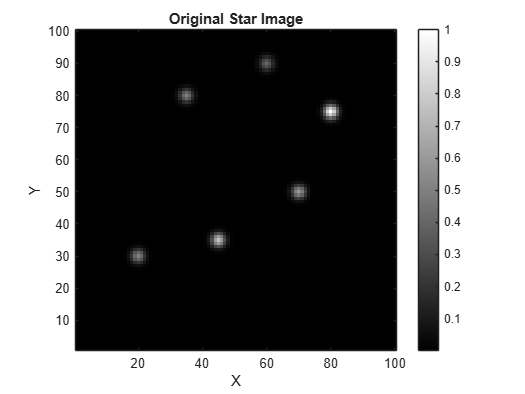



%% ============================================================
% 13. NORMALISE RECONSTRUCTION
% ============================================================

reconstructedImage = ...
    estimate ./ max(estimate(:));


normalisedTrueImage = ...
    trueImage ./ max(trueImage(:));


%% ============================================================
% 14. DISPLAY ORIGINAL IMAGE
% ============================================================

figure;

imagesc(normalisedTrueImage);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('Original Star Image');

xlabel('X');
ylabel('Y');

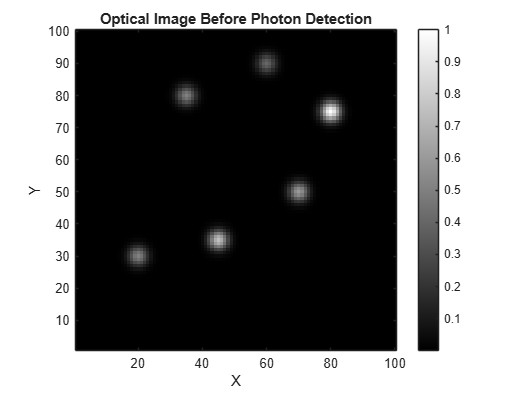



%% ============================================================
% 15. DISPLAY BLURRED MEASUREMENT
% ============================================================

figure;

imagesc(blurredImage ./ max(blurredImage(:)));

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('Optical Image Before Photon Detection');

xlabel('X');
ylabel('Y');

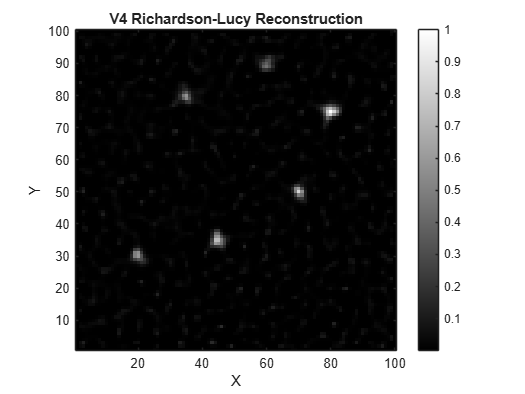



%% ============================================================
% 16. DISPLAY RECONSTRUCTED IMAGE
% ============================================================

figure;

imagesc(reconstructedImage);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('V3 Richardson-Lucy Reconstruction');

xlabel('X');
ylabel('Y');

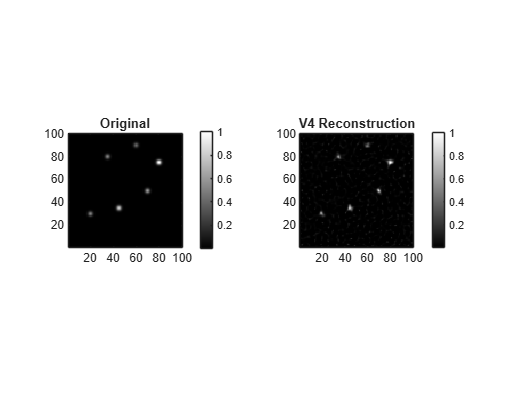



%% ============================================================
% 17. ORIGINAL VS RECONSTRUCTED
% ============================================================

figure;


subplot(1,2,1);

imagesc(normalisedTrueImage);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('Original');


subplot(1,2,2);

imagesc(reconstructedImage);

axis image;

set(gca,'YDir','normal');

colormap(gray);
colorbar;

title('V3 Reconstruction');



%% ============================================================
% 18. IMAGE QUALITY
% ============================================================

RMSE = sqrt( ...
    mean( ...
    (normalisedTrueImage(:) - ...
    reconstructedImage(:)).^2 ) );


correlationMatrix = ...
    corrcoef( ...
    normalisedTrueImage(:), ...
    reconstructedImage(:));


correlationCoefficient = ...
    correlationMatrix(1,2);


%% ============================================================
% 19. RESULTS
% ============================================================

fprintf('\n');
fprintf('============================================\n');

fprintf('V3 RECONSTRUCTION RESULTS\n');

V4 RECONSTRUCTION RESULTS


fprintf('============================================\n');


fprintf('Fibre diameter: %.1f um\n', ...
    FIBRE_DIAMETER_UM);

Fibre diameter: 4.2 um



fprintf('Angular sampling: %.4f arcsec\n', ...
    angularSamplingArcsec);

Angular sampling: 0.1341 arcsec



fprintf('PDE: %.0f %%\n',PDE*100);

PDE: 65 %



fprintf('Dark count rate: %.1f Hz\n', ...
    DARK_COUNT_RATE);

Dark count rate: 101.0 Hz



fprintf('Integration time: %.3f s\n', ...
    INTEGRATION_TIME);

Integration time: 0.100 s



fprintf('Photon scale: %.1e\n', ...
    PHOTON_SCALE);

Photon scale: 1.0e-04



fprintf('RL iterations: %d\n', ...
    NUM_ITERATIONS);

RL iterations: 30



fprintf('\n');

fprintf('RMSE: %.5f\n',RMSE);

RMSE: 0.02118



fprintf('Correlation: %.4f\n', ...
    correlationCoefficient);

Correlation: 0.8991



fprintf('============================================\n');



%% ============================================================
% 20. SAVE RESULTS
% ============================================================

save('SPC_Reconstruction_V3.mat', ...
    'trueImage', ...
    'measuredCounts', ...
    'signalCounts', ...
    'reconstructedImage', ...
    'systemPSF', ...
    'PDE', ...
    'DARK_COUNT_RATE', ...
    'INTEGRATION_TIME', ...
    'PHOTON_SCALE', ...
    'NUM_ITERATIONS', ...
    'RMSE', ...
    'correlationCoefficient');

fprintf('\nV3 data saved.\n');


V4 data saved.
